Predicting debris state (position and velocity)

clc;
clear all;

mu = 398600; %Standard gravitational parameter km3/s2
earthRadius = 6371; %km
orbitHeight = 600; %km
meanMotion = sqrt(mu/(earthRadius+orbitHeight)^3); % rad/s
n=meanMotion; %for simplicity

gravity = 9.81; %m/s2
dryMass = 3 ; % kg
fuelMass = 1; %kg
totalMass = dryMass+fuelMass;
massFlow = 0.01; %kg/s for a monopropellant spacecraft
maxThrust = 0.01; % kgkm/s2
maxAcc = maxThrust/totalMass;

%Implementing MPC
% Hill's Equations (State-Space Model)
% Continuous-time system dynamics
A = [0, 0, 0, 1, 0, 0; 
     0, 0, 0, 0, 1, 0; 
     0, 0, 0, 0, 0, 1;
     3*n^2, 0, 0, 0, 2*n, 0;
     0, 0, 0, -2*n, 0, 0;
     0, 0, -n^2, 0, 0, 0];
B = [0, 0, 0; 
     0, 0, 0; 
     0, 0, 0; 
     1, 0, 0; 
     0, 1, 0; 
     0, 0, 1];
C = eye(6); 
D = zeros(6, 3); 

% Discretization 
Ts = 3; % Sampling time (seconds)
sysc = ss(A, B, C, D); % Continuous-time state-space model
sysd = c2d(sysc, Ts); % Discrete-time state-space model
Ad = sysd.A;
Bd = sysd.B;

% Create the MPC Controller
mpc_controller = mpc(sysd, Ts);

-->"PredictionHorizon" is empty. Assuming default 10.
-->"ControlHorizon" is empty. Assuming default 2.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 y2 y3 and zero weight for output(s) y4 y5 y6 



% Define MPC Parameters
mpc_controller.PredictionHorizon = 30; % Predict 50 steps ahead
mpc_controller.ControlHorizon = 20; % Optimize for 20 steps
mpc_controller.Weights.ManipulatedVariables = [1, 1, 1]; % Input effort, Control input for minimizing fuel
mpc_controller.Weights.ManipulatedVariablesRate = [5, 5, 5]; % Input change rate, smoothens the trajectory
mpc_controller.Weights.OutputVariables = [1, 1, 1, 0.5, 0.5, 0.5]; % State weights - position with 1 is tracked better than velocity for better position safety margin

% Input Constraints (e.g., thrust limits)
mpc_controller.ManipulatedVariables(1).Min = -maxAcc; % Thrust x min (km/s^2)
mpc_controller.ManipulatedVariables(1).Max = maxAcc;  % Thrust x max (km/s^2)
mpc_controller.ManipulatedVariables(2).Min = -maxAcc; % Thrust y min (km/s^2)
mpc_controller.ManipulatedVariables(2).Max = maxAcc;  % Thrust y max (km/s^2)
mpc_controller.ManipulatedVariables(3).Min = -maxAcc; % Thrust z min (km/s^2)
mpc_controller.ManipulatedVariables(3).Max = maxAcc;  % Thrust z max (km/s^2)

% Output Constraint margin distance
mpc_controller.OutputVariables(2).Min = 0.001 % km for safety purposes

 
MPC object (created on 13-Jan-2025 19:58:09):
---------------------------------------------
Sampling time:      3 (seconds)
Prediction Horizon: 30
Control Horizon:    20

Plant Model:        
                                      --------------
      3  manipulated variable(s)   -->|  6 states  |
                                      |            |-->  6 measured output(s)
      0  measured disturbance(s)   -->|  3 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  6 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpc_controller)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: [1 1 1]
    ManipulatedVariablesRate: [5 5 5]
             OutputVariables: [1 1 1 0.5000 0.5000 0.5000]
                         ECR: 100000

State Estim

% Radial and tangential distance cannot be between 1 and -1 m
% Need to add constraint for that

%collision avoidance parameters
safeDistance = 0.05; %km
num_debris =3;

% Terminal Constraints for Position and Velocity
terminalPositionY = [0.001, 0.005]; % 1 to 5 meters (converted to km)
terminalVelocityY = [-0.00022, 0.00022]; % ≤ 0.22 m/s (converted to km/s)

% Define terminal constraints
term.Weight = [10, 10, 10, 5, 5, 5]; % Weight on terminal state (used higher weights for stricter constraints)
term.Min = [-Inf, terminalPositionY(1), -Inf, -Inf, terminalVelocityY(1), -Inf]; % Lower bounds
term.Max = [Inf, terminalPositionY(2), Inf, Inf, terminalVelocityY(2), Inf];     % Upper bounds
term.MinECR = [0, 0, 0, 0, 0, 0]; % Soft constraint penalties for violating lower bounds
term.MaxECR = [0, 0, 0, 0, 0, 0]; % Soft constraint penalties for violating upper bounds

% Apply terminal constraints to the MPC controller
setterminal(mpc_controller, term);

% Rocket Equation parameters
m0 = fuelMass; % Initial fuel mass (kg)
Isp = maxThrust/(massFlow * gravity); % Specific impulse (seconds)
ve = Isp * gravity; % Exhaust velocity (m/s)
fuel_history = []; % To track fuel usage

% Simulation Parameters
x0 = [0; 5; 0; 0; 0; 0]; % Initial state (5 km behind target)
ref = [0; 0; 0; 0; 0; 0]; % Target position and velocity

%initialize the MPCSTATE object
mpc_state=mpcstate(mpc_controller);

-->Assuming output disturbance added to measured output #1 is integrated white noise.
   Assuming no disturbance added to measured output #2.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->Assuming output disturbance added to measured output #4 is integrated white noise.
-->Assuming output disturbance added to measured output #5 is integrated white noise.
-->Assuming output disturbance added to measured output #6 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.



% Simulate Closed-Loop System
Tsim = 1500; % Total simulation time
x = x0; % Initialize state
u_history = []; % Input control history
x_history = x0';

% State vector of dynamic debris
debris_statevector =[0,0.08,0,0,0.0002,0.0006;       %debris 1
                     0,0.550,0.0002,0.000,0.00,0.000;%debris 2
                     0.005,0.05,0.05,0,0.002,0];     %no of debris X 6 dimension of array
debris_history=[];

for t = 0:Ts:Tsim

    %get debris position
    debris_pos = debris_statevector(:,1:3);

    %add collision avoidance constraint
    for i = 1:num_debris
        x_debris = debris_statevector(i, 1);
        y_debris = debris_statevector(i, 2);
        z_debris = debris_statevector(i, 3);
        vx_debris = debris_statevector(i, 4);
        vy_debris = debris_statevector(i, 5);
        vz_debris = debris_statevector(i, 6);

        [x_new, y_new, z_new, vx_new, vy_new, vz_new] = cal_hill(x_debris, y_debris, z_debris, vx_debris, vy_debris, vz_debris,n,t);
        debris_statevector(i, :) = [x_new, y_new, z_new, vx_new, vy_new, vz_new];

        % Calculate squared distance between chaser and debris (for all directions)
        distance_squared = (x(1) - x_new)^2 + (x(2) - y_new)^2 + (x(3) - z_new)^2;

        % Check if the distance is within the safe range
        if distance_squared < safeDistance^2

            % Define the collision avoidance constraint for all directions
            % position >= 50 + debrisdistance
            E = zeros(3,3); % Identity matrix for all three directions (thrust in x, y, z)
            F = eye(6); % Identity matrix for output variables (position in x, y, z)
            F(4,4)=0;
            F(5,5)=0;
            F(6,6)=0;
            G = safeDistance^2 - distance_squared; % Right-hand side constraint

            % Set the constraint for collision avoidance in all directions
            setconstraint(mpc_controller, E, F, G);
        end
    end

    % Compute MPC Control Action
    [u,mpcstate] = mpcmove(mpc_controller, mpc_state,x, ref);
    
    % Calculate Delta-V (change in velocity) for each direction
    deltaV_x = u(1) * Ts;  % Delta-V in the x direction (m/s)
    deltaV_y = u(2) * Ts;  % Delta-V in the y direction (m/s)
    deltaV_z = u(3) * Ts;  % Delta-V in the z direction (m/s)
    deltaV = sqrt(deltaV_x^2 + deltaV_y^2 + deltaV_z^2);  % Total Delta-V (m/s)
    
    % Fuel consumption based on Tsiolkovsky Rocket Equation
    mf = m0 * exp(-deltaV / ve);  % Final mass after fuel burn (kg)
    fuel_used = m0 - mf;  % Fuel used (kg)
    
    % Update initial mass for the next iteration (account for fuel burn)
    m0 = mf;

    % Apply Control Action (Update State)
    x = Ad * x + Bd * u;
    
    % Log Data
    u_history = [u_history; u'];
    x_history = [x_history; x'];
    fuel_history = [fuel_history; fuel_used];  % Log fuel usage
    debris_history = [debris_history;debris_statevector]; % log debris trajectory info
end

-->Not enough rows in matrix E, adding zeros.
-->Not enough entries in vector G, adding zeros.


-->Assuming output disturbance added to measured output #1 is integrated white noise.
   Assuming no disturbance added to measured output #2.
-->Assuming output disturbance added to measured output #3 is integrated white noise.
-->Assuming output disturbance added to measured output #4 is integrated white noise.
-->Assuming output disturbance added to measured output #5 is integrated white noise.
-->Assuming output disturbance added to measured output #6 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


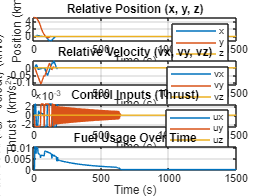


% Correct time vector
time = 0:Ts:Tsim; % Matches the number of states recorded in x_history
x_history = x_history(1:length(time), :); % Trim x_history to match time vector

figure;
subplot(4, 1, 1);
plot(time, x_history(:, 1:3)); % Plot position (x, y, z)
title('Relative Position (x, y, z)');
xlabel('Time (s)');
ylabel('Position (km)');
legend('x', 'y', 'z');
grid on;

subplot(4, 1, 2);
plot(time, x_history(:, 4:6)); % Plot velocity (vx, vy, vz)
title('Relative Velocity (vx, vy, vz)');
xlabel('Time (s)');
ylabel('Velocity (km/s)');
legend('vx', 'vy', 'vz');
grid on;

subplot(4, 1, 3); 
plot(time, u_history); % Plot control input 
title('Control Inputs (Thrust)');
xlabel('Time (s)');
ylabel('Thrust (km/s^2)');
legend('ux', 'uy', 'uz');
grid on;

subplot(4,1,4);
plot(time, fuel_history); % Plot fuel usage
title('Fuel Usage Over Time');
xlabel('Time (s)');
ylabel('Fuel Used (kg)');
grid on;

%calculate fuel usage
total_fuel_used = sum(fuel_history);  % Total fuel used over the entire simulation time
disp(['Total Fuel Used: ', num2str(total_fuel_used), ' kg']);

Total Fuel Used: 0.74474 kg


3D Visualisation

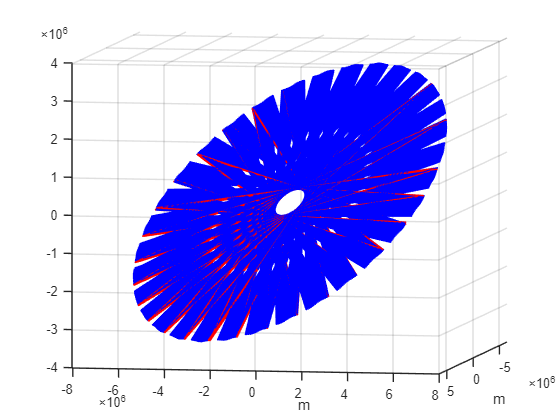

% 3D Visualization Setup
epochYear = 2024;
epochMonth = 1;
epochDay = 7;
epochHour = 0;
epochMinute = 0;
epochSecond = 0;
epoch = datetime(epochYear, epochMonth, epochDay, epochHour, epochMinute, epochSecond);

startTime = epoch;
stopTime = startTime + seconds(Tsim);
sampleTime = Ts; % seconds

semiMajorAxis = 7000000; % m
eccentricity = 0;
inclination = 0; % degrees
rightAscensionOfAscendingNode = 0; % degrees
argumentOfPeriapsis = 0; % degrees
trueAnomaly = 0; % degrees

% Create the satellite scenario
sc = satelliteScenario(startTime, stopTime, sampleTime);

% Convert Target's Keplerian Elements to Cartesian (Inertial Frame)
mu = 3.986004418e14; % Standard gravitational parameter (m^3/s^2)


% Add target satellite with orbital parameters (e.g., same orbit as chaser)
%target = satellite(sc,semiMajorAxis, eccentricity,inclination,rightAscensionOfAscendingNode,argumentOfPeriapsis,trueAnomaly,"OrbitPropagator","sgp4",'Name', 'Target'); % 700 km orbit altitude

% Chaser's Relative Position (x_history) and Velocity (v_history)
% Assuming these are precomputed relative states
chaserRelPos = x_history(:, 1:3); % Relative position (x, y, z) km
chaserRelVel = x_history(:, 4:6); % Relative velocity (vx, vy, vz) km

% Convert from LVLH to ECI for chaser's position and velocity
timeSteps = startTime + seconds((0:size(chaserRelPos, 1)-1) * sampleTime);
chaserTrajectory.Pos = zeros(size(chaserRelPos, 1), 3);
chaserTrajectory.Vel = zeros(size(chaserRelVel, 1), 3);

targetPosArray=[];
targetVelArray=[];

for i = 1:size(chaserRelPos, 1)

    [targetPos, targetVel] = propagateOrbit(i*Ts,semiMajorAxis, eccentricity, inclination, rightAscensionOfAscendingNode, argumentOfPeriapsis,trueAnomaly,'OutputCoordinateFrame','inertial','Epoch',epoch);

    % Calculate relative position and velocity in LVLH frame
    chaserRelPosLvlh = chaserRelPos(i, :) * 1000; % Convert to meters
    chaserRelVelLvlh = chaserRelVel(i, :) * 1000; % Convert to meters per second

    % Normalize target position and velocity to compute the LVLH to ECI rotation matrix
    targetPosNorm = targetPos / norm(targetPos); % Radial vector (i)
    targetVelNorm = targetVel / norm(targetVel); % Tangential velocity direction

    % Calculate normal vector (k) via cross product
    normalVector = cross(targetPosNorm, targetVelNorm);
    normalVector = normalVector / norm(normalVector);

    % Calculate tangential vector (j) perpendicular to both radial and normal
    tangentialVector = cross(normalVector, targetPosNorm);

    % Rotation matrix from LVLH to ECI
    R_eci2lvlh = [targetPosNorm, tangentialVector, normalVector];
    R_lvlh2eci = R_eci2lvlh';

    % Convert relative position and velocity from LVLH to ECI
    chaserAbsPos = (R_lvlh2eci * chaserRelPosLvlh')' + targetPos'; % Absolute position in ECI
    chaserAbsVel = (R_lvlh2eci * chaserRelVelLvlh')' + targetVel'; % Absolute velocity in ECI

    % Store in trajectory
    chaserTrajectory.Pos(i, :) = chaserAbsPos;
    chaserTrajectory.Vel(i, :) = chaserAbsVel;
    targetPosArray=[targetPosArray;targetPos'];
    tagrtetVelArray=[targetVelArray;targetVel'];

end

% Create Timetable
chaserTrajectoryTable = timetable(timeSteps', chaserTrajectory.Pos, chaserTrajectory.Vel, ...
    'VariableNames', {'Position', 'Velocity'});
%chaser = satellite(sc, chaserTrajectoryTable, 'Name', 'Chaser','CoordinateFrame','inertial');

% Create a new figure for animation
figure;
hold on;
grid on;
xlabel('m');
ylabel('m');
view(3);

% Create animated lines for chaser and target
chaserLine = animatedline('Color', 'r', 'LineWidth', 1.5);
targetLine = animatedline('Color', 'b', 'LineWidth', 1.5);

% Animation loop
for k = 1:length(timeSteps)

    % Add points to the chaser line
    addpoints(chaserLine, chaserTrajectory.Pos(k, 1), chaserTrajectory.Pos(k, 2), chaserTrajectory.Pos(k, 3));

    % Optional: Update target line (if desired)
    addpoints(targetLine, targetPosArray(k,1), targetPosArray(k,2), targetPosArray(k,3));

    % Update the figure
    drawnow;
    pause(0.005);
end


%{
pointAt(chaser, target);

% Launch the satellite scenario viewer
v = satelliteScenarioViewer(sc, 'CameraReferenceFrame', "Inertial");

% Set the 3D models for both satellites - upgrade matlab
chaser.Visual3DModel = "SmallSat.glb";
chaser.Visual3DModelScale = 0.8;
target.Visual3DModel = "SmallSat.glb";
target.Visual3DModelScale = 0.8;

% Display coordinate axes for both chaser and target
coordinateAxes([chaser, target], 'Scale', 2);

% Hide the orbits to focus on the satellites' positions
hide(chaser.Orbit);
hide(target.Orbit);

% Update the satellite scenario visualization
play(sc);
pause(sampleTime);  % Simulate with a delay between each timestep

% Camera follows the chaser satellite
camtarget(v, chaser);
campos(v, 0, 0, 200000);  % Set camera position (adjust values if needed)
%}